addpath('rx', 'tx','channel');
savepath;
Message = 'Hello bobr!';

%variant 4: len = 65, Nb = 8, Tcp = 1/4, dRS = 3, B = 11, f0 = 1.7

%Paremetrs
dRS = 3;
T = 0.25;
Nb = 8;
N0 = 0;
B = 11;
f0 = 1.7;

%Tx
encodedBits = symbolic_encoder(Message);
convEncodedBits = convolutional_encoder(encodedBits);
interleavedBits = interleaving(convEncodedBits);
qpskSymbols = QPSK_mapper(interleavedBits);
disp(qpskSymbols);

  Columns 1 through 9

   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i  -0.7070 - 0.7070i  -0.7070 - 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i

  Columns 10 through 18

  -0.7070 + 0.7070i  -0.7070 + 0.7070i  -0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i

  Columns 19 through 27

   0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 - 0.7070i  -0.7070 - 0.7070i  -0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i  -0.7070 - 0.7070i

  Columns 28 through 36

  -0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i

  Columns 37 through 45

  -0.7070 - 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i  -0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 - 0.7070i  -0.7070 - 0.7070i

  Columns 46

ofdmSymbols = ofdm_modulator(qpskSymbols, dRS, T);
disp(ofdmSymbols);

  Columns 1 through 9

   0.0178 - 0.0420i  -0.0570 + 0.0224i   0.0251 - 0.0305i   0.0015 + 0.0251i  -0.0111 + 0.0586i   0.0128 - 0.0639i   0.0146 - 0.0086i   0.0029 - 0.0124i  -0.0830 + 0.0609i

  Columns 10 through 18

   0.0696 - 0.0547i   0.0407 + 0.0585i  -0.0584 - 0.0350i  -0.0070 - 0.0193i   0.0122 + 0.0177i   0.0156 - 0.0199i  -0.0065 + 0.0480i  -0.0220 - 0.0110i   0.0498 - 0.0316i

  Columns 19 through 27

  -0.0503 + 0.0185i   0.0341 - 0.0095i  -0.0396 - 0.0100i   0.0023 + 0.0228i   0.0553 + 0.0282i   0.0219 - 0.0362i  -0.1055 - 0.0203i   0.0052 + 0.0044i   0.0524 + 0.0245i

  Columns 28 through 36

   0.0421 + 0.0169i  -0.0131 - 0.0063i  -0.0979 - 0.0605i   0.0436 + 0.0630i   0.0294 - 0.0266i   0.0141 + 0.0118i  -0.0188 - 0.0038i  -0.0228 - 0.0181i   0.0097 + 0.0436i

  Columns 37 through 45

   0.0209 - 0.0123i  -0.0334 - 0.0433i   0.0218 + 0.0147i   0.0071 + 0.0040i  -0.0127 + 0.0537i   0.0376 - 0.0122i  -0.0662 - 0.0485i  -0.0333 - 0.0859i   0.1495 + 0.1656i

  Columns 46

%CHANNEL
AWGNbits = channel(ofdmSymbols, Nb, N0);
disp(AWGNbits);

   1.0e+04 *

  Columns 1 through 9

   1.0429 - 2.4648i  -3.3403 + 1.3132i   1.4708 - 1.7856i   0.0904 + 1.4701i  -0.6522 + 3.4341i   0.7485 - 3.7438i   0.8554 - 0.5049i   0.1673 - 0.7242i  -4.8686 + 3.5691i

  Columns 10 through 18

   4.0808 - 3.2092i   2.3850 + 3.4324i  -3.4257 - 2.0494i  -0.4080 - 1.1286i   0.7162 + 1.0383i   0.9135 - 1.1660i  -0.3807 + 2.8140i  -1.2891 - 0.6458i   2.9186 - 1.8499i

  Columns 19 through 27

  -2.9461 + 1.0826i   1.9979 - 0.5569i  -2.3219 - 0.5886i   0.1321 + 1.3388i   3.2415 + 1.6552i   1.2836 - 2.1194i  -6.1839 - 1.1928i   0.3023 + 0.2574i   3.0702 + 1.4349i

  Columns 28 through 36

   2.4690 + 0.9899i  -0.7678 - 0.3707i  -5.7392 - 3.5475i   2.5569 + 3.6906i   1.7234 - 1.5623i   0.8265 + 0.6911i  -1.1016 - 0.2228i  -1.3388 - 1.0628i   0.5702 + 2.5559i

  Columns 37 through 45

   1.2262 - 0.7225i  -1.9579 - 2.5383i   1.2797 + 0.8609i   0.4136 + 0.2341i  -0.7458 + 3.1468i   2.2073 - 0.7154i  -3.8786 - 2.8417i  -1.9495 - 5.0334i   8.7634 + 9.7108i

%Rx
rx_ofdmSymbols = ofdm_demodulator(AWGNbits);
qpskDemodulatedBits = QPSK_demapper(rx_ofdmSymbols);
disp(qpskDemodulatedBits);

  Columns 1 through 28

     0     0     0     0     0     1     1     0     0     1     1     1     1     1     0     0     0     0     1     0     1     0     1     1     0     0     1     0

  Columns 29 through 56

     0     1     0     0     1     0     0     1     0     0     0     1     0     1     1     1     1     0     1     0     0     0     0     0     1     1     1     0

  Columns 57 through 84

     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     1     1     1     0     0     0     0     0     0     0     1     1     1

  Columns 85 through 112

     0     0     1     1     1     1     0     1     1     1     1     1     1     0     1     0     0     1     1     1     1     1     0     1     0     1     0     1

  Columns 113 through 140

     1     0     0     0     1     1     0     1     1     0     0     0     0     0     0     1     1     0     1     1     0     0     0     0     0     1     1     0

  Columns 141 through 1

deInterleavedBits = deinterleaving(qpskDemodulatedBits);
decodedBits = convolutional_decoder_viterbi(deInterleavedBits);
decodeMessage = symbolic_decoder(decodedBits);


%CHECK
if isequal(Message, decodeMessage)
    disp('Successfuly!');
    disp(['Original message: ', Message]);
    disp(['Decoded message: ', decodeMessage]);
else
    disp('Failed!');
    disp(['Original message: ', Message]);
    disp(['Decoded message: ', decodeMessage]);
end

Successfuly!


Original message: Hello bobr!


Decoded message: Hello bobr!


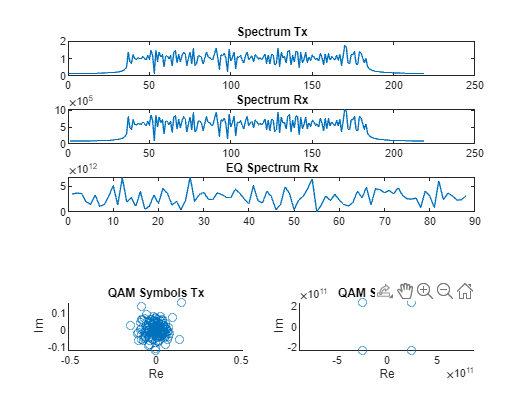

figure;

qpskTx = ofdmSymbols;
qpskRx = rx_ofdmSymbols;
spectrumTx = abs(fft(ofdmSymbols));
spectrumRx = abs(fft(AWGNbits));
spectrumEq = abs(fft(rx_ofdmSymbols));

% Верхние 3 графика (спектры)
subplot(5,1,1);
plot(spectrumTx);
title('Spectrum Tx');

subplot(5,1,2);
plot(spectrumRx);
title('Spectrum Rx');

subplot(5,1,3);
plot(spectrumEq);
title('EQ Spectrum Rx');

% Нижние 2 графика (QAM Symbols Rx)
subplot(5,2,9);
scatter(real(qpskTx), imag(qpskTx));
title('QAM Symbols Tx');
xlabel('Re'); ylabel('Im');
axis equal;

subplot(5,2,10);
scatter(real(qpskRx), imag(qpskRx));
title('QAM Symbols Rx');
xlabel('Re'); ylabel('Im');
axis equal;